# Polyphase Channelizer Model Initialization

This function initializes the MATLAB model of a polyphase channelizer to run on Versal devices.

The channelizer consists of a circular input buffer, a polyphase filter, a cyclic shift buffer, an IFFT (implemented as a DFT) operation, and an output buffer. The channelizer signal flow is depicted below:

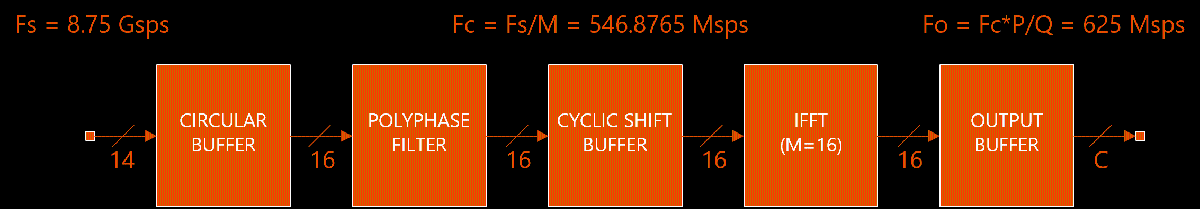

The design is simulated by the [channelizer_model](matlab:open('channelizer_model.mlx')) function.

function [app] = channelizer_init( TT, FF )

app = [];

## Basic Channelizer Parameters

This design uses the following parameters:

- Fs = 8.75 Gsps

- M = 16 channels

- Oversampling ratio P/Q = 8 / 7.

- Each channel has Fc = Fs/M = 546.8765 Msps

- Output rate Fo = Fc * P/Q = 625 Msps

- SSR = 8

app.fs_Gsps = 8.75;
app.Mchan = 16;
app.P = 8; 
app.Q = 7;
app.oversamp_ratio = app.Mchan*app.Q/app.P;
app.fc_Msps = 1000 * app.fs_Gsps / app.Mchan;
app.fs_Msps = app.fc_Msps * app.P / app.Q;

## Input Signal Parameters

Place signals into the following channels:

app.chan_id = [1 3 4 9 12];

Specify the number of samples per channel to match the depth of DDR PL Data Movers. To yield a desired 512 x 4 samples per stream, we need to scale down by 16 since channelizer model scales up 'dac_o' by this amount.

app.Nsamp_per_chan = 512 / 16 * 4; 
app.Nsamp = app.Q * app.Nsamp_per_chan;

## Signal Transmit Filter Parameters 

Peak-to-peak ripple, attenuation, passband and stopband boundaries, coefficients

app.sig_passband_ripple_dB = 0.10;            
app.sig_stopband_attenu_dB = -80;
app.sig_passband = 0.50;                    
app.sig_stopband = 0.65;                    
fp = app.sig_passband * 0.5 * app.fc_Msps;
fs = app.sig_stopband * 0.5 * app.fc_Msps;
ripple = [0.5*(10^(0.05*app.sig_passband_ripple_dB)-1),10^(0.05*app.sig_stopband_attenu_dB)];
app.taps_sig = firgr('minevn',[0,fp,fs,0.5*app.fc_Msps]/(0.5*app.fc_Msps),[1,1,0,0],ripple);

## Polyphase Filter Parameters

One-sided bandwidth, number of taps, passband and stopband boundaries, coefficients

app.bw_trans_oneside = 45;
app.Ntaps = 8;
fp = (1-app.bw_trans_oneside/100) * (0.5*app.fc_Msps);
fs = (1+app.bw_trans_oneside/100) * (0.5*app.fc_Msps);
tmp = firgr(app.Ntaps*app.Mchan-2,[0,fp,fs,500*app.fs_Gsps]/(500*app.fs_Gsps),[1,1,0,0]);
taps = [zeros(1,1),tmp];
taps = double(fi(taps,TT,FF));
app.taps = reshape(taps,app.Mchan,[]);
app.taps_tx = reshape(app.Mchan*app.taps,app.Mchan,[]); % Note scale factor due to interpolation

## Cyclic Shift Parameters

app.Ncyclic = lcm(app.Mchan,app.oversamp_ratio)/app.oversamp_ratio;
app.Nshift = app.Mchan / app.Ncyclic;   
end